**Clustering Method Notebook**

**Kuan-Min Lee**

**Clustering Method:**

**Basic Theory explanations:**

**Citation: Lecture: Clustering Analysis and K-Mean by Nabel Gopalan from Goergia Tech.**

Segments an image into K number of clusters. The goal of clustering is to decide objects into groups and objects within a group **are more similar to those outside the group.**

**Relative function:**

**imagekmenas(I,k)**

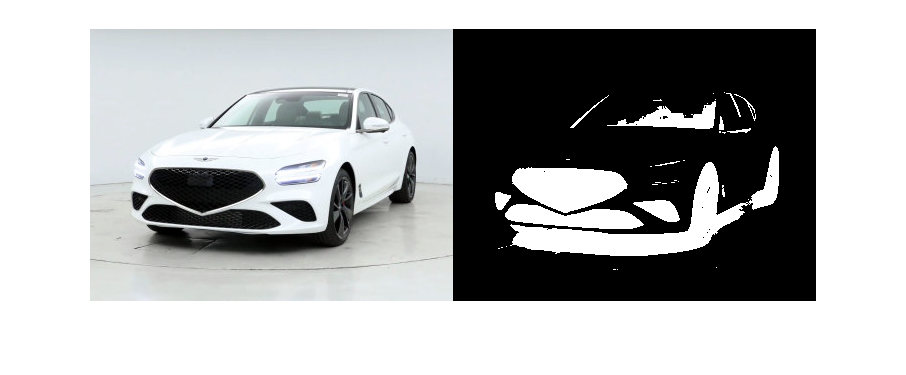

car_img=imread("car.jpg"); % read in sample image
car_img_BW=rgb2gray(car_img);
k_mean_car_img=imsegkmeans(car_img,2); % perform k mean clustering
imshowpair(car_img,k_mean_car_img,'montage')

From the above result, it can be seen that the k-mean algorithm sort the entire image into two regions (shadow and lightness) , which typically not what we want. Therefore, followed the procedure in matlab website, a set of 24 Gabor filters (6 wavelengths and 4 orientations) is inserted to improve its sorting ability.

Gaor filters can be seen as way for extracting texture feature in the image. It contains two controlling factor: Gabor wavelength and rotation angle. By inserting these two factors, Gabov filters will try to find out whether the texture with a certain frequency (wavelength and rotation angle) is existed withing the image:

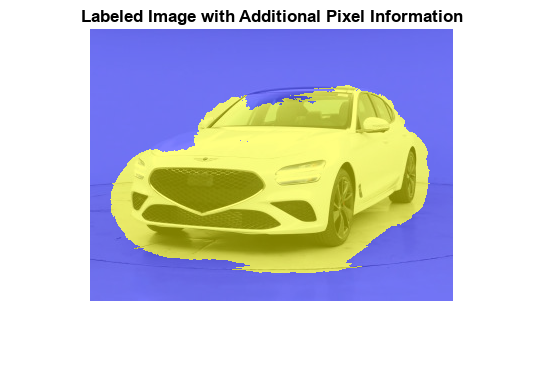

wavelength = 2.^(0:5) * 3; % insert three different wavelengths
orientation = 0:45:135; % insert 4 different orientation
g = gabor(wavelength,orientation);
car_img_BW = im2gray(im2single(car_img)); % convert it into grayscale
gabormag = imgaborfilt(car_img_BW,g); % conduct gabor filtering
% smoothe each gabor image (need fo
for i = 1:length(g)
    sigma = 0.5*g(i).Wavelength;
    gabormag(:,:,i) = imgaussfilt(gabormag(:,:,i),3*sigma); 
end
nrows = size(car_img,1);
ncols = size(car_img,2);
[X,Y] = meshgrid(1:ncols,1:nrows);
featureSet = cat(3,car_img,gabormag,X,Y);
L2 = imsegkmeans(featureSet,2,"NormalizeInput",true);
C = labeloverlay(car_img,L2);
imshow(C)
title("Labeled Image with Additional Pixel Information")

From the above imrpvement, the category can be obseerved to perform better since it has successfully sort most of the car into the right category. 

**Pros and Cons:**

**Pros:**

- Unlike threshold mathod, it can perform **multi category segmentation**

- It can sort out the image based on the feature sets provided in the dataset (like the second part of the testing)

**Cons:**

- Its performance can be dependent on the **features provided in the dataset, which might be hard to utilize since we might not know what features should we go for**

- K-mean algorithm depends the **number of k being utilized into the algorithm, which might be confusing since the users might not know the appropriate number of k that should be used in the algorithm**